clear,clc;

templateFiled = struct('p',0,'u',0,'rho',0,'gamma',5/3,'c',-1,'z',[0,0],'en',0,'range',[0,0],'type','unkown');
numFiled = 5;
filed = repmat(templateFiled,numFiled,1);

filed(1).u = 0;
filed(1).rho = 1;
filed(1).p = 1;

filed(2).u = 0;
filed(2).rho = 0.125;
filed(2).p = 0.1;

% 第一步，判断左右两侧是激波还是膨胀波
[filed(1), filed(2)] = waveType(filed(1),filed(2));
fprintf('假设是空气，则gamma为 %d\n',filed(1).gamma);

假设是空气，则gamma为 1.666667e+00


fprintf('filed 1 %s\n',filed(1).type);

filed 1 rarewave


fprintf('filed 2 %s\n',filed(2).type);

filed 2 shock


% 第二步，求解中心区（即三四区）压力和速度，
p_0 = (filed(1).p + filed(2).p)/2; % 初始预测的p*
f = @(p) F_1_2(p,filed(1),filed(2)) - filed(1).u + filed(2).u;
p_0 = fzero(f,p_0); % 
u_0 = 1/2*(filed(1).u + filed(2).u + F(p_0,filed(2)) - F(p_0,filed(1)));
fprintf('中心区 p = %d, u = %d\n',p_0,u_0);

中心区 p = 2.486722e-01, u = 9.409353e-01



filed(3).u = u_0;
filed(4).u = u_0;
filed(3).p = p_0;
filed(4).p = p_0;

% 第三步，确定中心区接触间断两侧密度
filed(3) = getRhoZ(filed(1),filed(3));
filed(4) = getRhoZ(filed(2),filed(4));

% 第四步，计算稀疏波区域的值即5区，如果存在的话
flag = false;
for i = 1:2
    if strcmpi(filed(i).type,'rarewave') || strmcpi(filed(i).type,'rarewave_vacuum')
        flag = true;
        filed(5) = getRareFiled(filed(i),filed(5));
        break;
    end
end

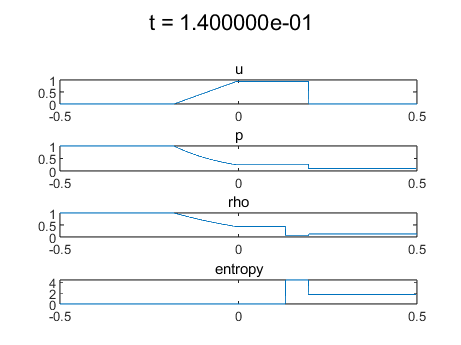

% 绘图展示
x_min = -0.5;
x_max = 0.5;
h = 0.001;
x = x_min:h:x_max;

filed = getFiledRange(filed,x_min,x_max);

plot_filed = filed;

% 折线图
for t = 0:0.01:0.14
    clf();
    plot_sequence = [1,5,3,4,2];
    plot_filed = getTemFiled(filed, x, t, plot_sequence);
    sgtitle(sprintf('t = %d', t));
    showTemFiled(plot_filed,1);
end

% 等高线图
colormap('jet');

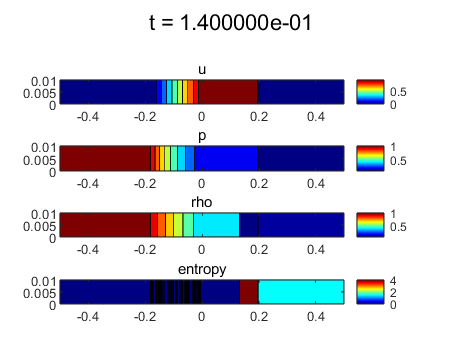

for t = 0:0.01:0.14
    clf();
    plot_sequence = [1,5,3,4,2];
    plot_filed = getTemFiled(filed, x, t, plot_sequence);
    sgtitle(sprintf('t = %d', t));
    showTemFiled(plot_filed,2);
end

% -------------------------FUNCTIONS---------------------------------------

% 给地区域，列表，绘制状态图, type = {1: 折线图， 2: 等高线图}

function showTemFiled(filed_list,type)
    x_plot = [];
    u_plot = [];
    p_plot = [];
    rho_plot = [];
    en_plot = [];
    for i = 1:5
        x_plot = [x_plot, filed_list(i).range];
        u_plot = [u_plot, filed_list(i).u];
        p_plot = [p_plot, filed_list(i).p];
        rho_plot = [rho_plot, filed_list(i).rho];
        en_plot = [en_plot, filed_list(i).en];
    end
    if type == 1
        subplot(411);
        plot(x_plot,u_plot);
        title('u');
        subplot(412);
        plot(x_plot,p_plot);
        title('p');
        subplot(413);
        plot(x_plot,rho_plot);
        title('rho')
        subplot(414);
        plot(x_plot,en_plot);
        title('entropy')
    else
        [X,Y] = meshgrid(x_plot, [0,0.01]);
        U = repmat(u_plot,2,1);
        P = repmat(p_plot,2,1);
        Rho = repmat(rho_plot,2,1);
        En = repmat(en_plot,2,1);
        subplot(411);
        contourf(X,Y,U);
        colorbar();
        title('u');
        subplot(412);
        contourf(X,Y,P);
        colorbar();
        title('p');
        subplot(413);
        contourf(X,Y,Rho);
        colorbar();
        title('rho')
        subplot(414);
        contourf(X,Y,En);
        title('entropy')
        colorbar();
    end
    pause(0.1);
end

% 给定x和t，求瞬态的区域值，按照seq的顺序返回
function tem_list = getTemFiled(filed_list, x, t, seq)
    tem_list = filed_list;
    for j = 1:5
        i = seq(j);
        range = filed_list(i).range(t);
        x_t = x(x >= range(1) & x < range(2));
        tem_list(j).range = x_t;
        gamma = filed_list(i).gamma;
        tem_list(j).u = getValue(filed_list(i).u,x_t,t);
        tem_list(j).p = getValue(filed_list(i).p,x_t,t);
        tem_list(j).rho = getValue(filed_list(i).rho,x_t,t);
        tem_list(j).en = log(tem_list(j).p ./ (tem_list(j).rho).^gamma) ./ (gamma - 1);
    end
end

function ret = getValue(f,x,t)
    if isa(f, 'function_handle')
        ret = f(x,t);
    else
        ret = repmat(f,1,length(x));
    end
end

function filed = getFiledRange(filed,x_min,x_max)
    % 左稀疏波,右激波
    if strcmpi(filed(1).type, 'rarewave') && strcmpi(filed(2).type,'shock')
        c_3 = getFiledC(filed(3));
        c_1 = getFiledC(filed(1));
        
        filed(1).range = @(t) [x_min,(filed(1).u - c_1)*t];
        filed(2).range = @(t) [filed(4).z*t,x_max];
        filed(3).range = @(t) [(filed(3).u - c_3)*t, filed(3).u*t];
        filed(4).range = @(t) [filed(4).u*t, filed(4).z*t];
        filed(5).range = @(t) [(filed(1).u - c_1)*t, (filed(3).u - c_3)*t];
    end
end

% 计算稀疏波内部的物理量
function filed_2 = getRareFiled(filed_1,filed_2)
    c_1 = getFiledC(filed_1);
    p_1 = filed_1.p;
    u_1 = filed_1.u;
    gamma = filed_1.gamma;

    c_2 =  @(x,t) (gamma-1)/(gamma+1) * (u_1-x/t) + 2/(gamma+1)*c_1;
    u_2 = @(x,t) c_2(x,t) + x/t;
    p_2 = @(x,t) p_1 * (c_2(x,t)/c_1).^(2*gamma / (gamma-1));
    rho_2 = @(x,t) gamma *  p_2(x,t) ./ c_2(x,t).^2;

    filed_2.c = c_2;
    filed_2.u = u_2;
    filed_2.p = p_2;
    filed_2.rho = rho_2;
   
end

% 根据不同的波形，计算当地密度波速
function filed_2 = getRhoZ(filed_1,filed_2)
    u = filed_1.u;
    rho = filed_1.rho;
    gamma = filed_1.gamma;
    c = getFiledC(filed_1);

    u_ = filed_2.u;
    p_ = filed_2.p;

    if strcmpi(filed_1.type, 'shock')
        % 激波
        [A,rho_] = getARho(filed_1,u_,p_);
        z = u + A/rho;
        
        filed_2.rho = rho_;
        filed_2.z = z;
    else
        % 稀疏波
        c_ = c + (gamma - 1) * (u - u_) / 2;
        rho_ = gamma * p_ / c_^2;
        z_h = u - c;
        z_t = u_ - c_;
        if strcmpi(filed_1.type, 'rarewave_vacuum')
            z_t = u - 2 / (gamma - 1) * c;
        end
        
        filed_2.rho = rho_;
        filed_2.c = c_;
        filed_2.z = [z_h,z_t];
    end
end

% 计算声速
function ret = getC(p,gamma,rho)
    ret = sqrt(p * gamma / rho);
end

% 获取区域当地声速c
function ret = getFiledC(filed)
%     if filed.c ~= -1
%         ret = filed.c;
%     else
        ret = getC(filed.p,filed.gamma,filed.rho);
%     end
end

% 左波为激波时候，根据当地速度计算当地密度rho*
function [A,rho_] = getARho(filed,u_,p_)
    rho = filed.rho;
    u = filed.u;
    gamma = filed.gamma;
    p = filed.p;
    c = getFiledC(filed);

    t = sqrt((gamma+1)/(2*gamma)*p_/p + (gamma-1)/(2*gamma));
    A = rho * c * sqrt(t);

    rho_ = rho * A / (A - rho * (u - u_) );
end

% 判断给定区域的波形，rare or shock
function [filed_1, filed_2] = waveType(filed_1, filed_2)
    p_1 = filed_1.p;
    p_2 = filed_2.p;
    u_1 = filed_1.u;
    u_2 = filed_2.u;
    
    % 保证 p_1 >= p_2
    if p_2 > p_1
        disp('p2 > p1');
        [filed_1, filed_2] = waveType(filed_2, filed_1);
    end

    d_u = u_1 - u_2;

    if d_u >= F_1_2(p_1,filed_1,filed_2)
        % 情况一，左右都是激波
        filed_1.type = 'shock';
        filed_2.type = 'shock';
    elseif d_u >=F_1_2(p_2,filed_1,filed_2)
        % 情况二，左激波，右膨胀波
        filed_1.type = 'rarewave';
        filed_2.type = 'shock';
    elseif d_u >= F_1_2(0,filed_1,filed_2)
        % 情况四，左右都是膨胀波
        filed_1.type = 'rarewave';
        filed_2.type = 'rarewave';
    else
        % 情况五，真空
        filed_1.type = 'rarewave_vacuum';
        filed_2.type = 'rarewave_vacuum';
    end
end

% 根据给定的p*，以及1区或2区的状态，求f(p*,p_i,rho_i)
function f_p = F(p, filed)
    if p > filed.p
        f_p = F_1(p,filed);
    else
        f_p = F_2(p,filed);
    end
end

% f(p*,p_1,rho_1) + f(p*,p_2,rho_2)
function ret = F_1_2(p,filed_1,filed_2)
    ret = F(p,filed_1) + F(p,filed_2);
end

% p* > p_i
function ret = F_1(p_,filed)
    rho = filed.rho;
    p = filed.p;
    c = getFiledC(filed);
    gamma = filed.gamma;
    
    ret = (p_ - p)/(rho*c*((gamma+1)/(2*gamma)*(p_/p)+(gamma-1)/(2*gamma))^1/2);
end

% p* < p_i
function ret = F_2(p_,filed)
    p = filed.p;
    c = getFiledC(filed);
    gamma = filed.gamma;

    ret = 2*c/(gamma-1)*((p_/p)^((gamma-1)/(2*gamma))-1);
end
